[y0,fs]=audioread("bluesky1.wav");
y=y0(1:8192,1);
y=y';
y=y.*32768;
tic;
Y1=fft(y);
t1=toc

t1 = 0.0052

tic;
Y2=MATLAB_ditfft(y);
t2=toc

t2 = 0.0142

tic;
Y3=MATLAB_dft(y);
t3=toc

t3 = 37.5474

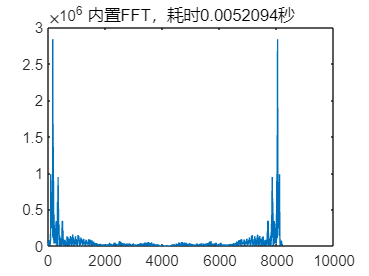


plot(abs(Y1));
title("内置FFT，耗时"+mat2str(t1)+"秒");

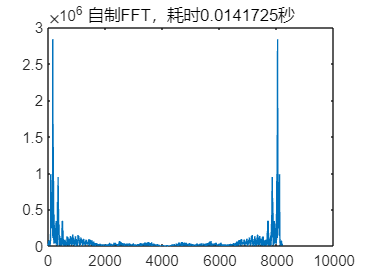

plot(abs(Y2));
title("自制FFT，耗时"+mat2str(t2)+"秒");

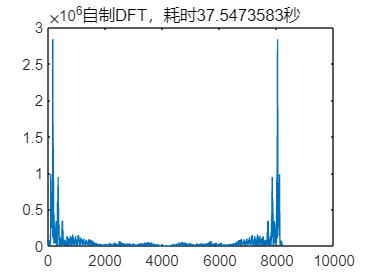

plot(abs(Y3));
title("自制DFT，耗时"+mat2str(t3)+"秒");